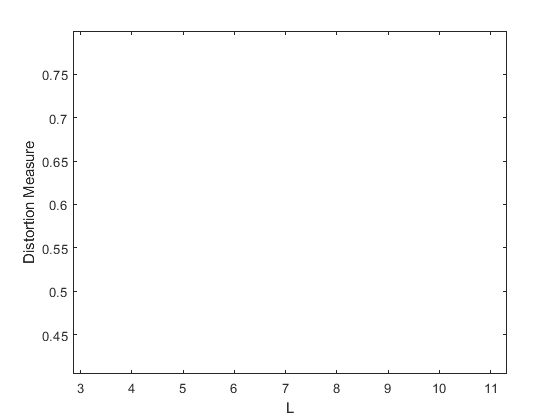

%K-means clustering
K = 2;               % number of clusters used
L = 15;              % number of iterations
scale_factor = 0.5;  % image downscale factor
image_sigma = 1;   % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);
[ segm, centers ,evol] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(42)
plot([0:L],evol, 'LineWidth', 2)
xlabel('L');
ylabel('Distortion Measure');

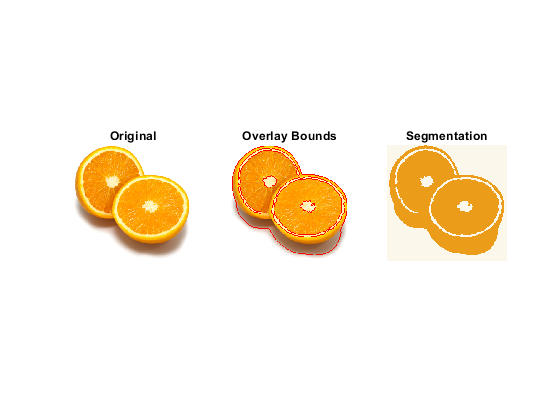


figure(43)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

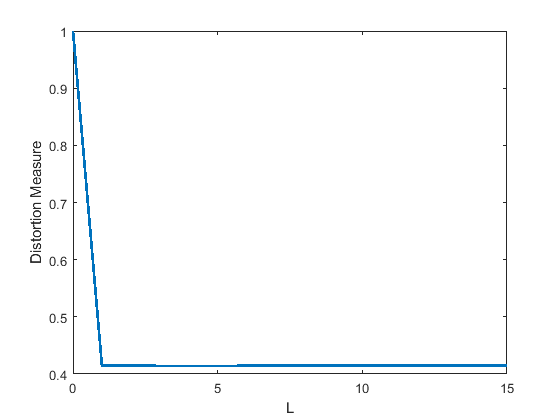

K = 3;               % number of clusters used
L = 15;              % number of iterations
scale_factor = 0.5;  % image downscale factor
image_sigma = 1;   % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);
[ segm, centers ,evol] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(44)
plot([0:L],evol, 'LineWidth', 2)
xlabel('L');
ylabel('Distortion Measure');

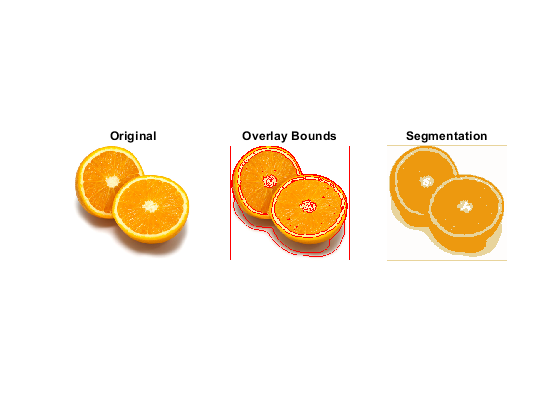


figure(45)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

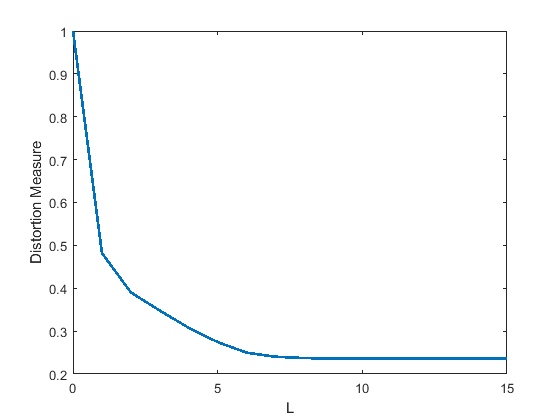

K = 4;               % number of clusters used
L = 15;              % number of iterations
scale_factor = 0.5;  % image downscale factor
image_sigma = 1;   % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);
[ segm, centers ,evol] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(42)
plot([0:L],evol, 'LineWidth', 2)
xlabel('L');
ylabel('Distortion Measure');

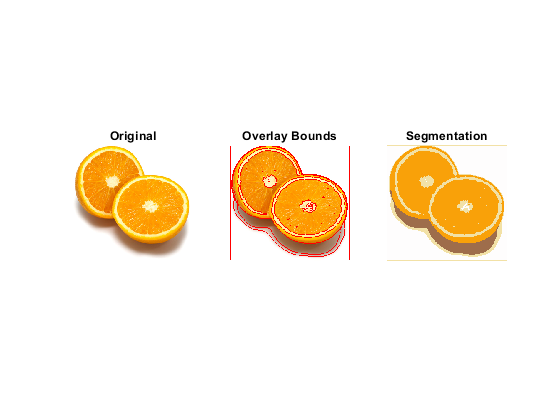


figure(43)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

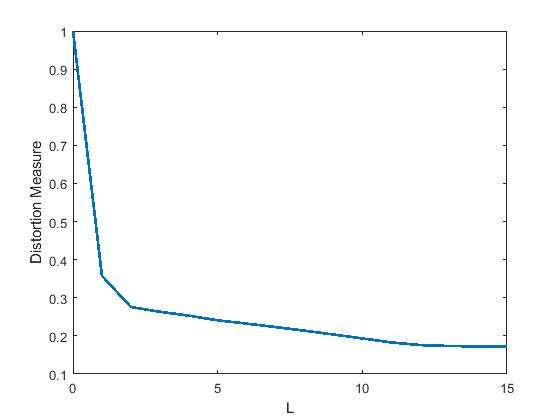

K = 5;               % number of clusters used
L = 15;              % number of iterations
scale_factor = 0.5;  % image downscale factor
image_sigma = 1;   % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);
[ segm, centers ,evol] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(70)
plot([0:L],evol, 'LineWidth', 2)
xlabel('L');
ylabel('Distortion Measure');

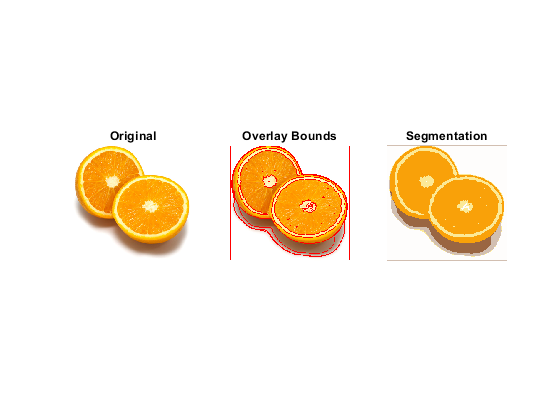


figure(71)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

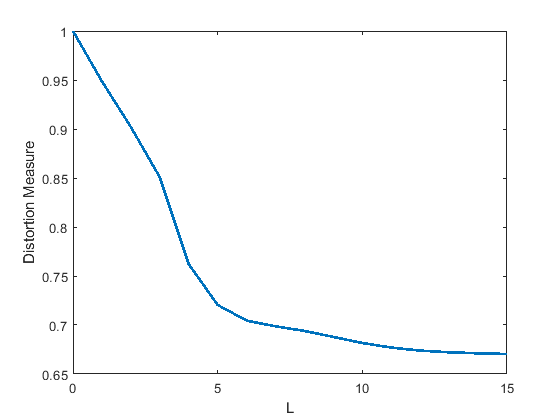

K = 6;               % number of clusters used
L = 15;              % number of iterations
scale_factor = 0.5;  % image downscale factor
image_sigma = 1;   % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);
[ segm, centers ,evol] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(72)
plot([0:L],evol, 'LineWidth', 2)
xlabel('L');
ylabel('Distortion Measure');

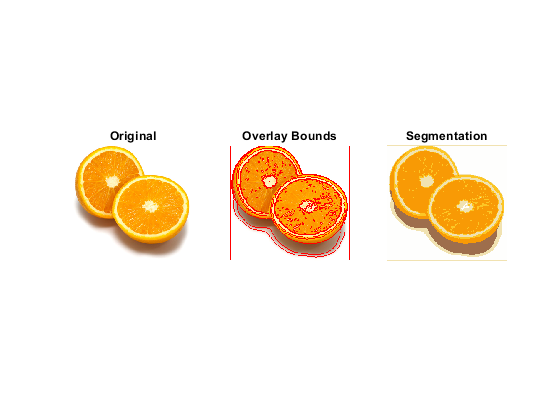


figure(73)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

%q4
K = 4;               % number of clusters used
L = 30;              % number of iterations
scale_factor = 0.5;  % image downscale factor
image_sigma = 1.0;   % image preblurring scale

I = imread('tiger1.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

Nruns = 2

Nruns = 2

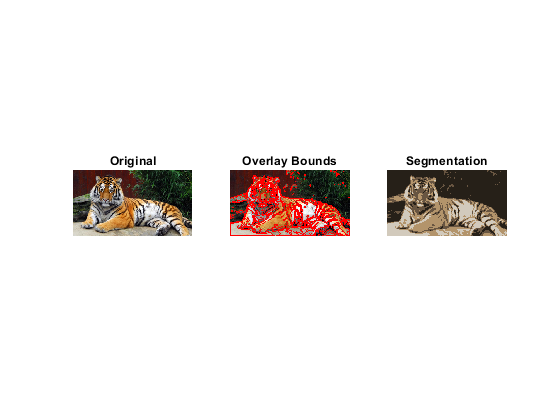

[ segm, centers, evol ] = kmeans_opt(I, K, L, Nruns);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(13)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

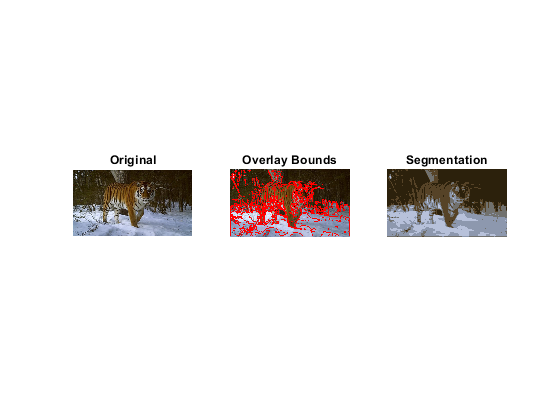

K = 5;               % number of clusters used
L = 30;              % number of iterations
scale_factor = 0.5;  % image downscale factor
image_sigma = 1.0;   % image preblurring scale

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

[ segm, centers, evol ] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(15)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

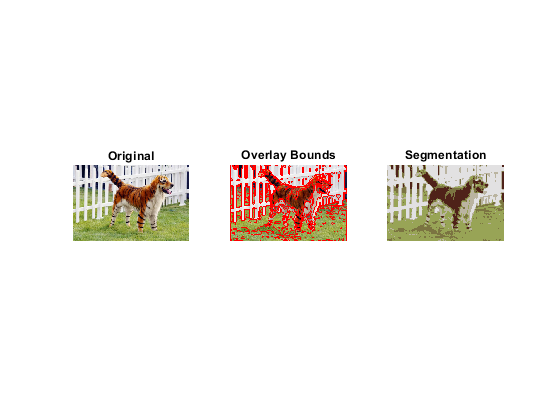

K = 5;               % number of clusters used
L = 30;              % number of iterations
scale_factor = 0.5;  % image downscale factor
image_sigma = 1.0;   % image preblurring scale

I = imread('tiger3.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

[ segm, centers, evol ] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(17)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

%Meanshift segmentation
% q5
scale_factor = 0.5;       % image downscale factor
spatial_bandwidth = 10;  % spatial bandwidth
colour_bandwidth = 5;  % colour bandwidth
num_iterations = 200;      % number of mean-shift iterations
image_sigma = 1.;        % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth,...
    num_iterations);

Find colour channels with K-means...
Search for high density points...


Assign high density points to pixels...


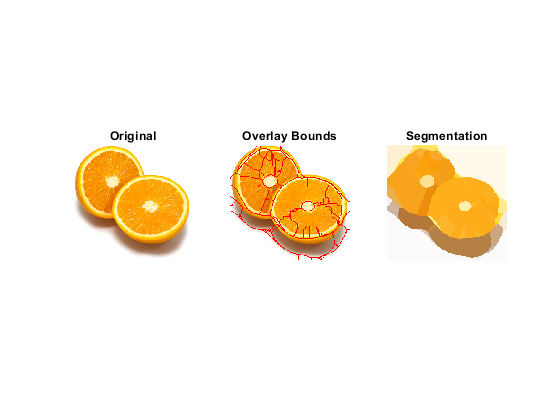

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(5)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

scale_factor = 0.5;       % image downscale factor
spatial_bandwidth = 20;  % spatial bandwidth
colour_bandwidth = 5;  % colour bandwidth
num_iterations = 200;      % number of mean-shift iterations
image_sigma = 1.;        % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth,...
    num_iterations);

Find colour channels with K-means...
Search for high density points...


Assign high density points to pixels...


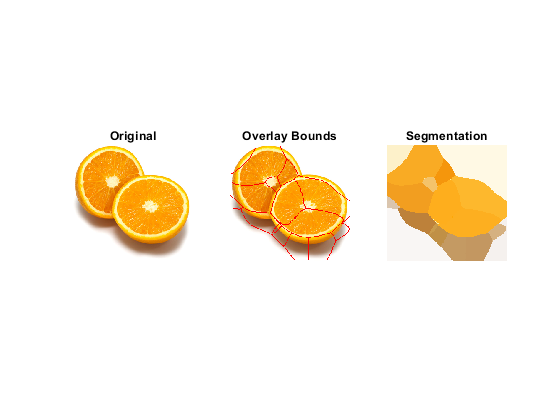

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(51)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

scale_factor = 0.5;       % image downscale factor
spatial_bandwidth = 4;  % spatial bandwidth
colour_bandwidth = 4;  % colour bandwidth
num_iterations = 200;      % number of mean-shift iterations
image_sigma = 1.;        % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth,...
    num_iterations);

Find colour channels with K-means...
Search for high density points...


Assign high density points to pixels...


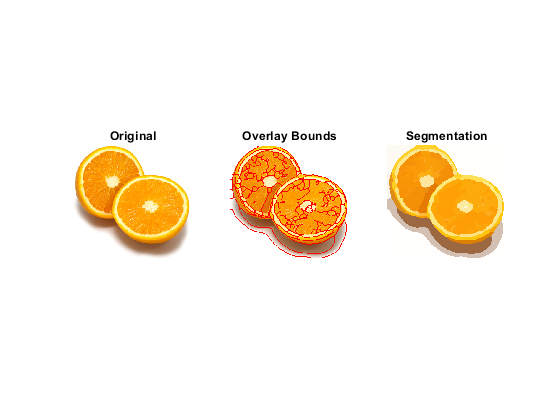

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(53)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

scale_factor = 0.5;       % image downscale factor
spatial_bandwidth = 5;  % spatial bandwidth
colour_bandwidth = 20;  % colour bandwidth
num_iterations = 200;      % number of mean-shift iterations
image_sigma = 1.;        % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth,...
    num_iterations);

Find colour channels with K-means...
Search for high density points...


Assign high density points to pixels...


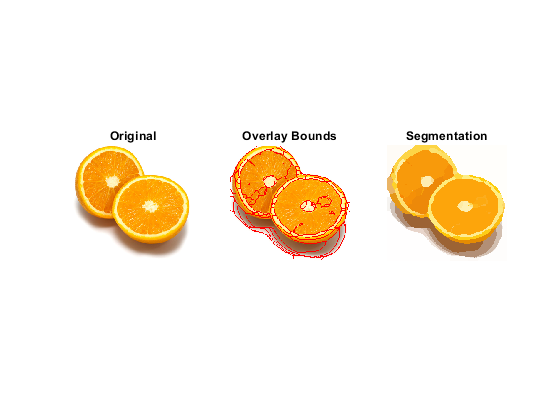

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(54)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

scale_factor = 0.5;       % image downscale factor
spatial_bandwidth = 10;  % spatial bandwidth
colour_bandwidth = 30;  % colour bandwidth
num_iterations = 200;      % number of mean-shift iterations
image_sigma = 1.;        % image preblurring scale

I = imread('tiger1.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth,...
    num_iterations);

Find colour channels with K-means...
Search for high density points...


Assign high density points to pixels...


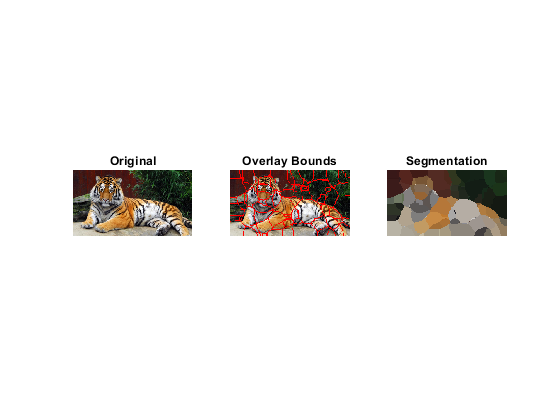

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(55)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

%Normalized cut
% q7
colour_bandwidth = 20.0; % color bandwidth
radius = 3;              % maximum neighbourhood distance
ncuts_thresh = 0.4;      % cutting threshold
min_area = 50;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 2.0;       % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);

Compute affinity matrix...
Solve eigenvalue problems to find partitions...
Cutting ncut=0.013 sizes=(35844,14765)
Cutting ncut=0.005 sizes=(13368,22476)
Cutting ncut=0.008 sizes=(10694,2674)
Cutting ncut=0.006 sizes=(3191,7503)
Cutting ncut=0.016 sizes=(1398,1793)
Cutting ncut=0.055 sizes=(716,682)
Cutting ncut=0.060 sizes=(241,475)
Cutting ncut=0.161 sizes=(114,127)
Cutting ncut=0.069 sizes=(83,31)
Cutting ncut=0.308 sizes=(39,88)
Cutting ncut=0.081 sizes=(252,223)
Cutting ncut=0.169 sizes=(130,122)
Cutting ncut=0.155 sizes=(75,148)
Cutting ncut=0.024 sizes=(267,415)
Cutting ncut=0.198 sizes=(166,101)
Cutting ncut=0.223 sizes=(83,83)
Cutting ncut=0.228 sizes=(46,55)
Cutting ncut=0.101 sizes=(136,279)
Cutting ncut=0.215 sizes=(87,49)
Cutting ncut=0.082 sizes=(216,63)
Cutting ncut=0.053 sizes=(867,926)
Cutting ncut=0.119 sizes=(381,486)
Cutting ncut=0.143 sizes=(195,186)
Cutting ncut=0.252 sizes=(90,105)
Cutting ncut=0.198 sizes=(104,82)
Cutting ncut=0.148 sizes=(362,124)
Cutting ncut=0

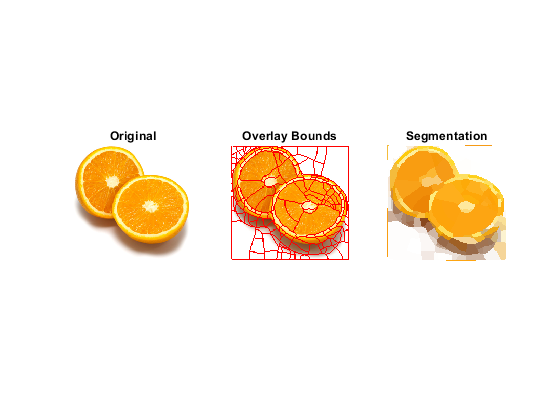

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(7)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

colour_bandwidth = 20.0; % color bandwidth
radius = 3;              % maximum neighbourhood distance
ncuts_thresh = 0.4;      % cutting threshold
min_area = 10;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 2.0;       % image preblurring scale

I = imread('tiger1.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);

Compute affinity matrix...
Solve eigenvalue problems to find partitions...
Cutting ncut=0.003 sizes=(18455,15137)
Cutting ncut=0.012 sizes=(8499,9956)
Cutting ncut=0.024 sizes=(2602,5897)
Cutting ncut=0.063 sizes=(1060,1542)
Cutting ncut=0.093 sizes=(636,424)
Cutting ncut=0.120 sizes=(321,315)
Cutting ncut=0.171 sizes=(168,153)
Cutting ncut=0.229 sizes=(84,84)
Cutting ncut=0.442 sizes=(44,40)
Cutting ncut=0.282 sizes=(22,62)
Cutting ncut=0.273 sizes=(80,73)
Cutting ncut=0.223 sizes=(23,57)
Cutting ncut=0.395 sizes=(38,35)
Cutting ncut=0.123 sizes=(228,87)
Cutting ncut=0.215 sizes=(67,161)
Cutting ncut=0.315 sizes=(35,32)
Cutting ncut=0.216 sizes=(128,33)
Cutting ncut=0.410 sizes=(43,44)
Cutting ncut=0.164 sizes=(247,177)
Cutting ncut=0.195 sizes=(127,120)
Cutting ncut=0.318 sizes=(69,58)
Cutting ncut=0.390 sizes=(35,34)
Cutting ncut=0.474 sizes=(29,29)
Cutting ncut=0.235 sizes=(94,26)
Cutting ncut=0.227 sizes=(59,35)
Cutting ncut=0.696 sizes=(13,13)
Cutting ncut=0.207 sizes=(96,81)
Cut

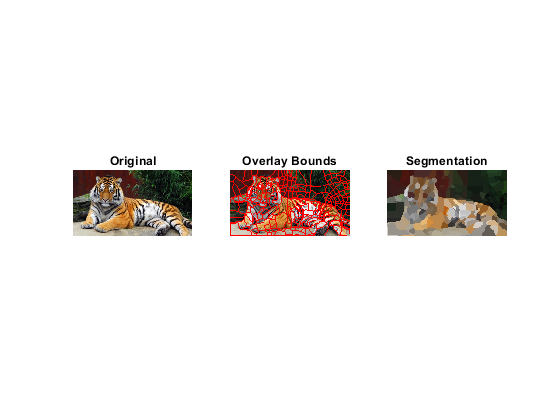

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(61)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

colour_bandwidth = 20.0; % color bandwidth
radius = 5;              % maximum neighbourhood distance
ncuts_thresh = 0.5;      % cutting threshold
min_area = 30;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 2.0;       % image preblurring scale

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);

Compute affinity matrix...
Solve eigenvalue problems to find partitions...
Cutting ncut=0.005 sizes=(22622,14242)
Cutting ncut=0.028 sizes=(12934,9688)
Cutting ncut=0.039 sizes=(9845,3089)
Cutting ncut=0.041 sizes=(6214,3631)
Cutting ncut=0.046 sizes=(1606,4608)
Cutting ncut=0.115 sizes=(835,771)
Cutting ncut=0.155 sizes=(497,338)
Cutting ncut=0.270 sizes=(238,259)
Cutting ncut=0.303 sizes=(13,225)
Cutting ncut=0.417 sizes=(140,119)
Cutting ncut=0.295 sizes=(28,310)
Cutting ncut=0.190 sizes=(397,374)
Cutting ncut=0.310 sizes=(162,235)
Cutting ncut=0.545 sizes=(68,94)
Cutting ncut=0.337 sizes=(117,118)
Cutting ncut=0.194 sizes=(263,111)
Cutting ncut=0.261 sizes=(237,26)
Cutting ncut=0.632 sizes=(56,55)
Cutting ncut=0.051 sizes=(3507,1101)
Cutting ncut=0.056 sizes=(760,2747)
Cutting ncut=0.169 sizes=(403,357)
Cutting ncut=0.229 sizes=(212,191)
Cutting ncut=0.363 sizes=(179,178)
Cutting ncut=0.070 sizes=(1872,875)
Cutting ncut=0.081 sizes=(1364,508)
Cutting ncut=0.183 sizes=(425,450)
Cutt

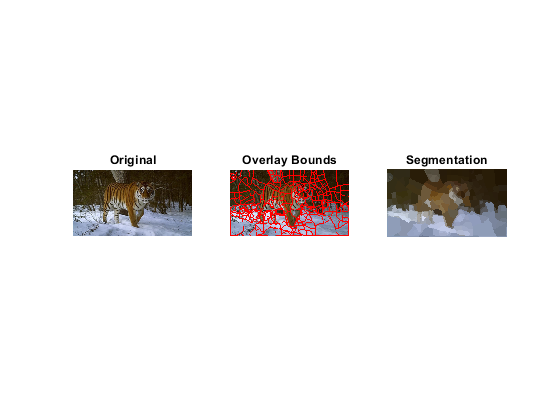

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(62)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

colour_bandwidth = 20.0; % color bandwidth
radius = 3;              % maximum neighbourhood distance
ncuts_thresh = 0.4;      % cutting threshold
min_area = 20;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 2.0;       % image preblurring scale

I = imread('tiger3.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);

Compute affinity matrix...
Solve eigenvalue problems to find partitions...
Cutting ncut=0.009 sizes=(19692,18228)
Cutting ncut=0.020 sizes=(9048,10644)
Cutting ncut=0.018 sizes=(4422,4626)
Cutting ncut=0.025 sizes=(2278,2144)
Cutting ncut=0.024 sizes=(1793,485)
Cutting ncut=0.054 sizes=(1232,561)
Cutting ncut=0.065 sizes=(218,1014)
Cutting ncut=0.171 sizes=(131,87)
Cutting ncut=0.133 sizes=(47,84)
Cutting ncut=0.328 sizes=(32,55)
Cutting ncut=0.060 sizes=(633,381)
Cutting ncut=0.062 sizes=(466,167)
Cutting ncut=0.134 sizes=(147,234)
Cutting ncut=0.122 sizes=(227,334)
Cutting ncut=0.087 sizes=(66,161)
Cutting ncut=0.226 sizes=(31,35)
Cutting ncut=0.146 sizes=(44,117)
Cutting ncut=0.130 sizes=(187,147)
Cutting ncut=0.290 sizes=(83,104)
Cutting ncut=0.185 sizes=(67,80)
Cutting ncut=0.091 sizes=(345,140)
Cutting ncut=0.188 sizes=(67,278)
Cutting ncut=0.251 sizes=(30,37)
Cutting ncut=0.224 sizes=(6,24)
Cutting ncut=0.206 sizes=(14,23)
Cutting ncut=0.185 sizes=(130,148)
Cutting ncut=0.160 si

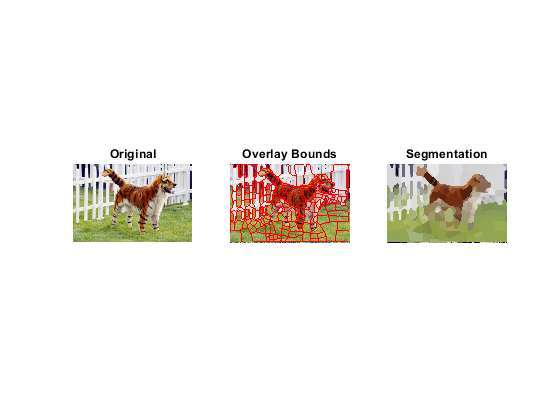

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(63)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

%q10
colour_bandwidth = 20.0; % color bandwidth
radius = 6;              % maximum neighbourhood distance
ncuts_thresh = 0.5;      % cutting threshold
min_area = 30;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 2.0;       % image preblurring scale

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);

Compute affinity matrix...
Solve eigenvalue problems to find partitions...
Cutting ncut=0.005 sizes=(22656,14208)
Cutting ncut=0.032 sizes=(9394,13262)
Cutting ncut=0.029 sizes=(5291,4103)
Cutting ncut=0.059 sizes=(3168,2123)
Cutting ncut=0.083 sizes=(1570,1598)
Cutting ncut=0.043 sizes=(571,999)
Cutting ncut=0.159 sizes=(346,225)
Cutting ncut=0.115 sizes=(193,153)
Cutting ncut=0.398 sizes=(121,72)
Cutting ncut=0.475 sizes=(60,93)
Cutting ncut=0.208 sizes=(146,79)
Cutting ncut=0.344 sizes=(48,98)
Cutting ncut=0.295 sizes=(18,61)
Cutting ncut=0.177 sizes=(639,360)
Cutting ncut=0.148 sizes=(83,556)
Cutting ncut=0.630 sizes=(40,43)
Cutting ncut=0.234 sizes=(343,213)
Cutting ncut=0.296 sizes=(156,204)
Cutting ncut=0.463 sizes=(96,60)
Cutting ncut=0.578 sizes=(78,126)
Cutting ncut=0.104 sizes=(429,1169)
Cutting ncut=0.261 sizes=(183,246)
Cutting ncut=0.342 sizes=(103,80)
Cutting ncut=0.471 sizes=(19,84)
Cutting ncut=0.637 sizes=(47,33)
Cutting ncut=0.274 sizes=(144,102)
Cutting ncut=0.445 s

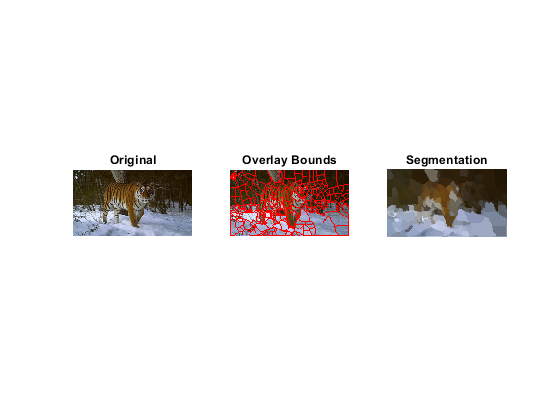

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(65)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation');

colour_bandwidth = 20.0; % color bandwidth
radius = 12;              % maximum neighbourhood distance
ncuts_thresh = 0.5;      % cutting threshold
min_area = 30;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 2.0;       % image preblurring scale

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);

Compute affinity matrix...
Solve eigenvalue problems to find partitions...
Cutting ncut=0.009 sizes=(17976,18888)
Cutting ncut=0.030 sizes=(9832,8144)
Cutting ncut=0.049 sizes=(996,8836)
Cutting ncut=0.153 sizes=(342,654)
Cutting ncut=0.180 sizes=(135,207)
Cutting ncut=0.770 sizes=(50,85)
Cutting ncut=0.320 sizes=(43,164)
Cutting ncut=0.768 sizes=(24,19)
Cutting ncut=0.588 sizes=(109,55)
Cutting ncut=0.279 sizes=(578,76)
Cutting ncut=0.386 sizes=(532,46)
Cutting ncut=0.390 sizes=(276,256)
Cutting ncut=0.501 sizes=(164,112)
Cutting ncut=0.349 sizes=(198,58)
Cutting ncut=0.631 sizes=(162,36)
Cutting ncut=0.825 sizes=(26,32)
Cutting ncut=0.681 sizes=(15,31)
Cutting ncut=0.408 sizes=(27,49)
Cutting ncut=0.027 sizes=(6789,2047)
Cutting ncut=0.136 sizes=(3364,3425)
Cutting ncut=0.168 sizes=(2011,1353)
Cutting ncut=0.274 sizes=(702,1309)
Cutting ncut=0.361 sizes=(91,611)
Cutting ncut=0.642 sizes=(52,39)
Cutting ncut=0.279 sizes=(499,112)
Cutting ncut=0.353 sizes=(684,625)
Cutting ncut=0.593 s

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(66)
subplot(1,3,1)
imshow(Iback)
title('Original');
subplot(1,3,2)
imshow(I)
title('Overlay Bounds');
subplot(1,3,3)
imshow(Inew)
title('Segmentation')

%segmentation using graph cuts
% q11
scale_factor =0.5;          % image downscale factor
area = [ 105, 149, 536, 280 ]; % image region to train foreground with
K = 3;                      % number of mixture components
alpha = 40;                 % maximum edge cost
sigma = 5;                % edge cost decay factor

I = imread('tiger1.jpg');
I = imresize(I, scale_factor);
Iback = I;
area = int16(area*scale_factor);
[ segm, prior ] = graphcut_segm(I, area, K,...
    alpha, sigma);

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 97. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 83. 



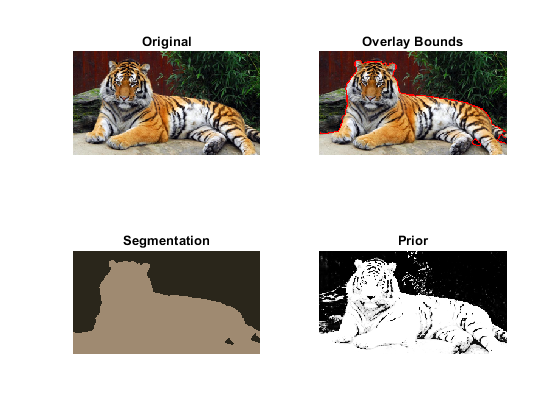


Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(81)
subplot(2,2,1)
imshow(Iback)
title('Original');
subplot(2,2,2)
imshow(I)
title('Overlay Bounds');
subplot(2,2,3)
imshow(Inew)
title('Segmentation');
subplot(2,2,4); 
imshow(prior);
title('Prior');

scale_factor =0.5;          % image downscale factor
area = [ 105, 149, 536, 280 ]; % image region to train foreground with
K = 3;                      % number of mixture components
alpha = 30.0;                 % maximum edge cost
sigma = 25;                % edge cost decay factor
I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
area = int16(area*scale_factor);
[ segm, prior ] = graphcut_segm(I, area, K,...
    alpha, sigma);

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 



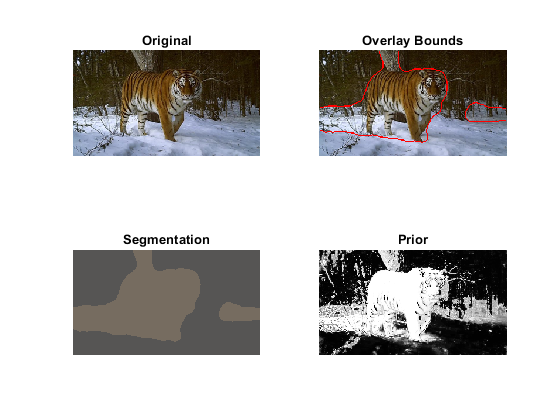


Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(9)
subplot(2,2,1)
imshow(Iback)
title('Original');
subplot(2,2,2)
imshow(I)
title('Overlay Bounds');
subplot(2,2,3)
imshow(Inew)
title('Segmentation');
subplot(2,2,4); 
imshow(prior);
title('Prior');

scale_factor =0.5;          % image downscale factor
area = [ 105, 149, 536, 280 ]; % image region to train foreground with
K = 3;                      % number of mixture components
alpha = 12.0;                 % maximum edge cost
sigma = 14;                % edge cost decay factor

I = imread('tiger3.jpg');
I = imresize(I, scale_factor);
Iback = I;
area = int16(area*scale_factor);
[ segm, prior ] = graphcut_segm(I, area, K,...
    alpha, sigma);

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 



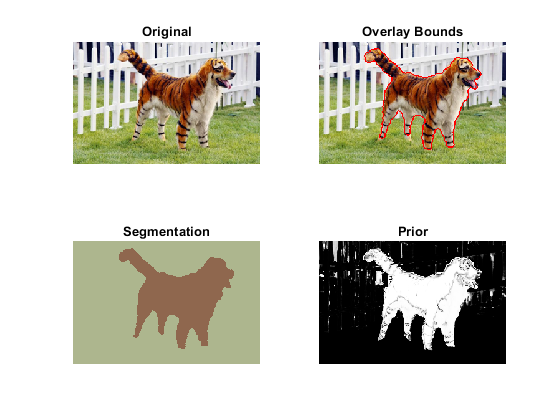


Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(82)
subplot(2,2,1)
imshow(Iback)
title('Original');
subplot(2,2,2)
imshow(I)
title('Overlay Bounds');
subplot(2,2,3)
imshow(Inew)
title('Segmentation');
subplot(2,2,4); 
imshow(prior);
title('Prior');

%q12
scale_factor =0.5;          % image downscale factor
area = [ 105, 149, 536, 280 ]; % image region to train foreground with
K = 2;                      % number of mixture components
alpha = 30.0;                 % maximum edge cost
sigma = 25;                % edge cost decay factor

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
area = int16(area*scale_factor);
[ segm, prior ] = graphcut_segm(I, area, K,...
    alpha, sigma);

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 



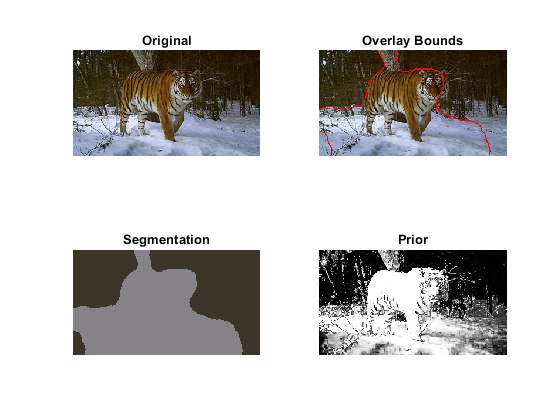


Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(89)
subplot(2,2,1)
imshow(Iback)
title('Original');
subplot(2,2,2)
imshow(I)
title('Overlay Bounds');
subplot(2,2,3)
imshow(Inew)
title('Segmentation');
subplot(2,2,4); 
imshow(prior);
title('Prior');

scale_factor =0.5;          % image downscale factor
area = [ 105, 149, 536, 280 ]; % image region to train foreground with
K = 4;                      % number of mixture components
alpha = 30.0;                 % maximum edge cost
sigma = 25;                % edge cost decay factor

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
area = int16(area*scale_factor);
[ segm, prior ] = graphcut_segm(I, area, K,...
    alpha, sigma);

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 



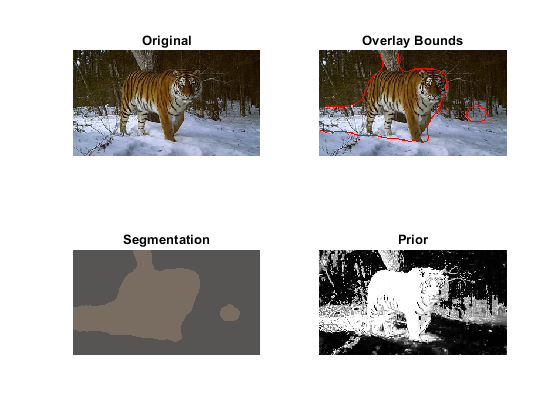

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 



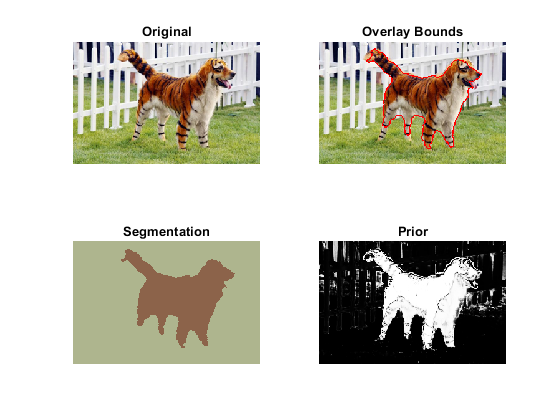

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 

Find Gaussian mixture models...
Find minimum cut...
number of iterations = 100. 



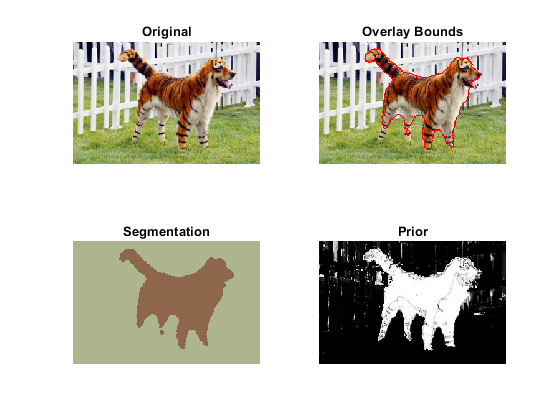


Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);

figure(90)
subplot(2,2,1)
imshow(Iback)
title('Original');
subplot(2,2,2)
imshow(I)
title('Overlay Bounds');
subplot(2,2,3)
imshow(Inew)
title('Segmentation');
subplot(2,2,4); 
imshow(prior);
title('Prior');